# Satellite Pose Estimation

This demo provides a solution to the satellite pose estimation problem. Here, this is done by:

- Loading the data, the wireframe model of the spacecraft, and using it to create the groundtruth for the two deep learning networks

- Using an object detection network based on Yolo v4 to detect and crop out the spacecraft in the images

- Using a keypoint detection network to predict the spacecraft keypoints

- Estimating the pose of the spacecraft using a PnP solver that compares the predicted keypoints to the wireframe model to predict the pose

## References

SPEED-UE-Cube Dataset

[1] Park, T.H., Ahmed, Z., Bhattacharjee, A., Razel-Rezai, R., Graves, R., Saarela, O., Teramoto, R., Vemulapalli, K., and D'Amico, S. (2024). Spacecraft Pose Estimation Dataset of a 3U CubeSat using Unreal Engine (SPEED-UE-Cube). Available at [https://purl.stanford.edu/hw812wb1641.](https://purl.stanford.edu/hw812wb1641.)

[2] Ahmed, Z., Park, T.H., Bhattacharjee, A., Razel-Rezai, R., Graves, R., Saarela, O., Teramoto, R., Vemulapalli, K., and D'Amico, S. SPEED-UE-Cube: A Machine Learning Dataset for Autonomous, Vision-Based Spacecraft Navigation. 46th Rocky Mountain AAS Guidance, Navigation and Control Conference, Breckenridge, Colorado, February 2-7, 2024

[3] Stanford Github repository for MATLAB deep learning training example: [https://github.com/tpark94/speed-ue-cube-baseline?tab=readme-ov-file](https://github.com/tpark94/speed-ue-cube-baseline?tab=readme-ov-file) 

## Setup

Setup parameters

% Run this to check proper configuration
% Start from a clean workspace
clearvars
 
if isfolder('SampleData')
    disp('You are in the correct directory. Please continue.')
    addpath('SampleData')
    addpath('HelperFiles')
else  
    error('Please navigate to the proper Directory')
end

You are in the correct directory. Please continue.


dataroot = "SampleData";
cubesatPointsFile = fullfile(dataroot, 'cubesatPoints.mat');
camerafn = fullfile(dataroot, 'camera.json');

### Load Data

Load the image dataset into an image datastore and the groundtruth JSON data into a table. This demo only used the "train" images in the dataset.

The image dataset consists of images of the CubeSat synthetically generated from the perspective of the camera in the ego spacecraft. The groundtruth consist rotation information in the form of quaternion and range information. A quaternion is a four-part hyper-complex number used in three-dimensional rotations and orientations. 

Load the camera parameters associated with this dataset that are generated in MATLAB and OpenCV format.

- **Images** are read using the `imageDatastore`

- **Range **or **position **information are read using `jsondecode` and are represented as a **three-element vector**

- **Orientation** quaternions are read using `jsondecode` and are represented as a **four-element vector**

- Orientation and range, along with image filenames, are combined into a single struct called `dataGroundTruth`

%  Load camera intrinsics & keypoints
camera = jsondecode(fileread(camerafn));

filePath = fullfile(dataroot, "train");

addpath(fullfile("HelperFiles"));

imds = imageDatastore(fullfile(filePath, "images"));
dataGroundTruth = jsondecode(fileread(fullfile(filePath, "train.json")));
%valDataGroundTruth = jsondecode(fileread(fullfile(filePath, "validation.json")));

[cameraParamMatlab,intrinsicsOpenCV] = cameraParameters_Cubesat(camera);

disp("Data loaded")

Data loaded


### Load Spacecraft Wireframe Keypoints

Run this code to load the saved wireframe model points.

The wireframe information can be obtained from a CAD model of the spacecraft. 

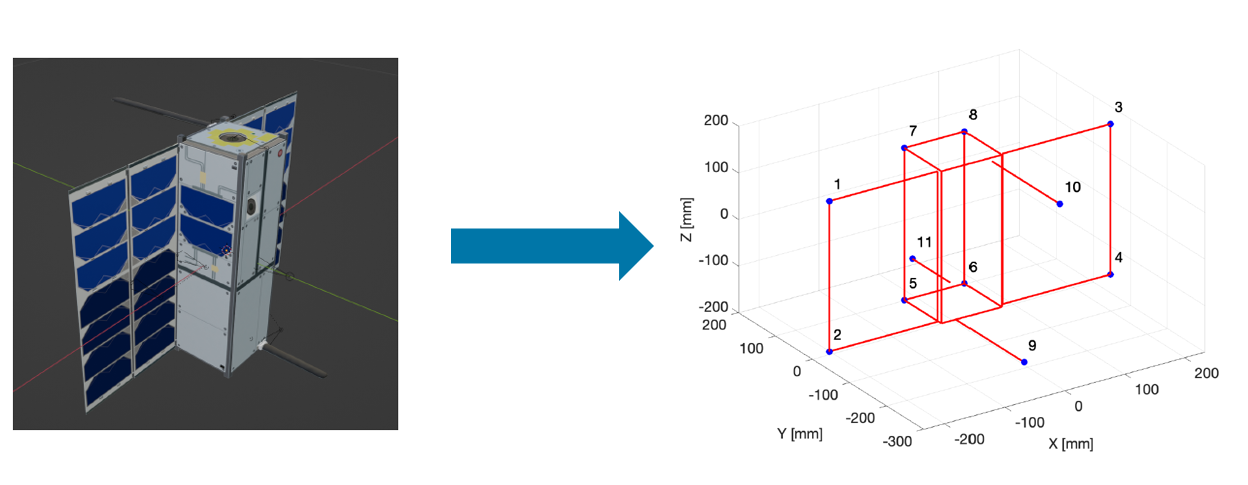

load(cubesatPointsFile, "sat3dPoints");
pointsTangoBodyRef = sat3dPoints';
disp("Wireframe model loaded")

Wireframe model loaded


### Select Sample Image

Select the image to use for calculations and to display as an example.

sampleSelector = 13;
kpts_gt = computeKeypointCoordinates(camera,dataGroundTruth(sampleSelector),sat3dPoints);
img = imread(fullfile(filePath, "images", dataGroundTruth(sampleSelector).filename + ".png"));
imshow(img); hold on; 
scatter(kpts_gt(1,:), kpts_gt(2,:), 16, 'gx', LineWidth=10);

title(["Spacecraft Image with 11 Keypoints"; "Projected from World to Image Frame"])

### Compute Axes Coordinates

For each image, we calculate its x, y, and z axis using the spacecraft quaternions and range from the groundtruth.

To display the axes of the spacecraft in the image, we compute the appropriate rotations of the camera axes into the frame of the spacecraft by converting quaternions into direction cosine matrices (DCMs) and applying matrix mutiplication (see inside the file `computeAxisCoordinates`).

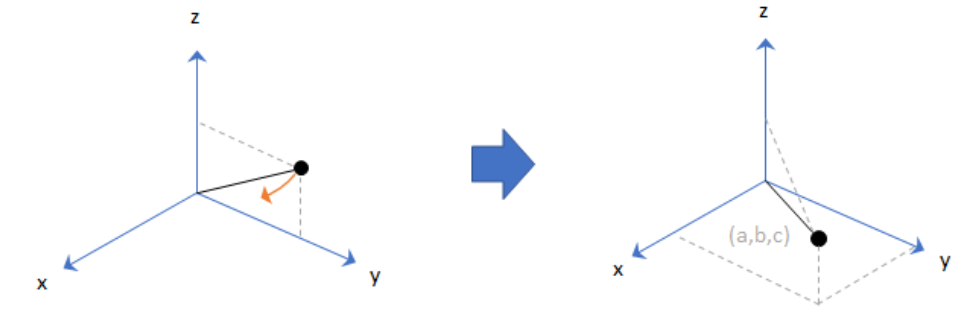

newCoordinateAxes = zeros(size(imds.Files,1),8);

for i = 1:length(dataGroundTruth)
    [newCoordinateAxes(i,:)] = computeAxisCoordinates(cameraParamMatlab,dataGroundTruth(i).q_vbs2tango_true',dataGroundTruth(i).r_Vo2To_vbs_true);
end

f = figure(); montage({plotSpacecraftAxes(readimage(imds,1),newCoordinateAxes(1,:)),...
    plotSpacecraftAxes(readimage(imds,2),newCoordinateAxes(2,:)),...
    plotSpacecraftAxes(readimage(imds,3),newCoordinateAxes(3,:)),...
    plotSpacecraftAxes(readimage(imds,4),newCoordinateAxes(4,:))});
title("Spacecraft Image with x, y and z Axis Projection")

## Object Detection Network (ODN)

### Detect Spacecraft in Images

You can use a deep learning approach or the edge detection approach to detect the spacecraft in the image and create a bounding box that contains it. For simplicity, we will be using the edge detection approach today, but this only works with images where the spacecraft is by itself against a background of outer space. If the Earth is in the background, then you need a more sophisticated detector such as a deep learning detector, which we will not be showing here.

To see how this network is trained, see citation [3] above. 

odn = load("odn_trained.mat", "net");

% Detect bbox with IoU threshold 0.5
[bbox_pr, scores, labels] = detect(odn.net, img, 'Threshold', 0.5); % [xmin, ymin, w, h] 
bbox_pr = double(bbox_pr);   

detectedImg = insertObjectAnnotation(img,"Rectangle",bbox_pr,labels,'FontSize',60,'LineWidth',8);
figure
imshow(detectedImg)
title("Spacecraft Image with Estimated Bounding Box")

## Keypoint Regression Network (KRN)

Because of limited time, we will not be training the model in this workshop. Instead, run this section to see how we create and train the keypoint regression network (KRN), which will be used throughout the following sections.

A diagram of the methodology is shown below:

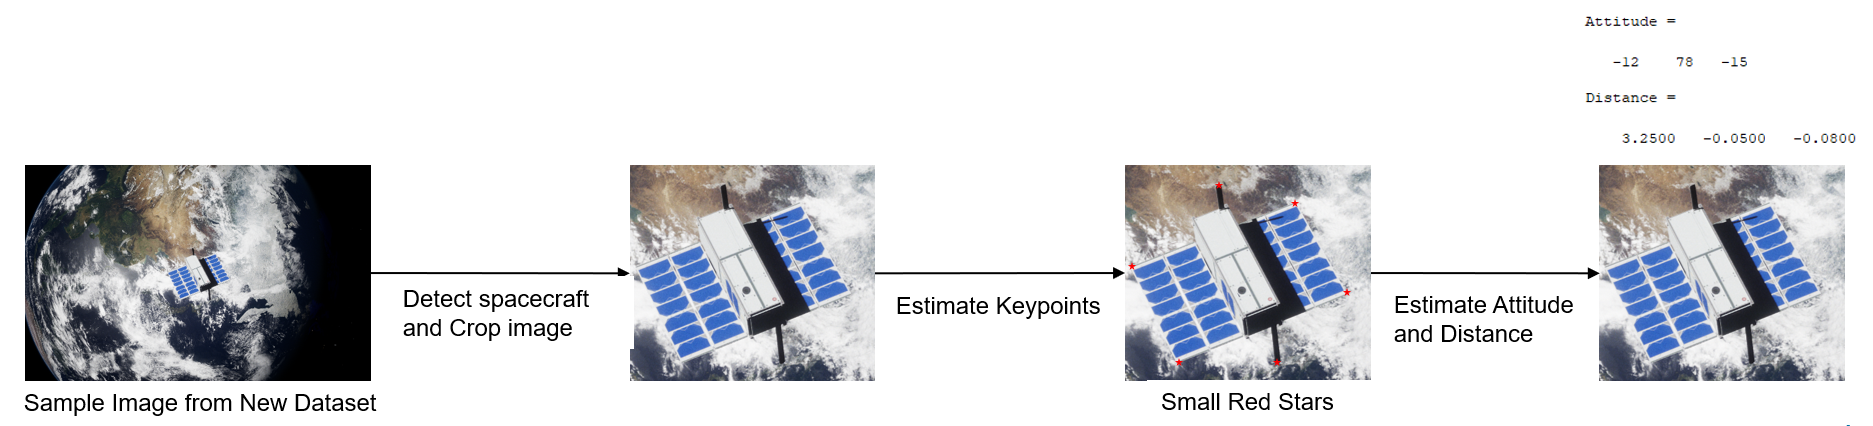

### Crop Image to Detected Satellite

First, we load in the trained keypoint regression network. This network is trained to take a cropped image of the satellite and predict the satellite's 11 keypoints.

krn = load("krn_trained.mat", 'net');
krnInputSize = [224, 224];

Next, we crop the image of the satellite from the results of the object detection network (ODN). 

% Process image with predicted bbox
% bbox = [xmin, ymin, w, h]
x = bbox_pr(1) + bbox_pr(3) / 2;
y = bbox_pr(2) + bbox_pr(4) / 2;
w = bbox_pr(3);
h = bbox_pr(4);
imgSize = size(img);
% Use getSquareRoI to pad the bounding box and keep the whole satellite in view
[xmin, ymin, xmax, ymax] = getSquareRoI(x, y, w, h, imgSize([2, 1]), false);
roi = [xmin, ymin, xmax - xmin, ymax - ymin]; % [xmin, ymin, w, h] (pix. org.)
imgCropped = imcrop(img, roi);
imgResized = imresize(imgCropped, krnInputSize);
imgResized  = im2single(imgResized);
imshow(imgResized)
title("Cropped CubeSat Image")

### Detect Keypoints of Satellite

Then, we pass this image into the KRN. The predicted points are converted from the 224 x 224 image to the original image and displayed on the original image. 

keypoints_pr = predict(krn.net, imgResized); 

% Predicted keypoints to [2 x 11] normalized keypoints
keypoints_pr = reshape(double(keypoints_pr), [2, 11]);
    
% Keypoints to pixels in original image
kpts_pr(1,:) = keypoints_pr(1,:) * (xmax - xmin) + xmin;
kpts_pr(2,:) = keypoints_pr(2,:) * (ymax - ymin) + ymin;

imshow(img);
hold on
scatter(kpts_pr(1,:), kpts_pr(2,:), 16, 'rx', LineWidth=10);
scatter(kpts_gt(1,:), kpts_gt(2,:), 16, 'gx', LineWidth=10);
axis([xmin xmax ymin ymax])
title("Predicted vs Actual Keypoints")
legend("Predicted", "Actual")
hold off

The Root Mean Square Error (RMSE) error of the mean of the difference between the predicted points and the groundtruth points is calculated.

pr = reshape(kpts_pr,[],1);
gt = reshape(kpts_gt,[],1);
rmse = sqrt(mean((gt - pr).^2))

rmse = 3.7794

## Perspective-n-Point (PnP) Solver

### Estimate the Relative Attitude and Range of the Target Spacecraft

Run this to use a PnP solver to estimate the relative attitude and range of the target spacecraft, calculate its error against the groundtruth, and plot its x, y and z axis.

The PnP solver used is the *estimateWorldCameraPose* function which takes the 11 predicted points in the image frame, the wireframe data (real world 3D coordinates) and the camera calibration parameters and estimates the camera attitude direction cosine matrix (dcm) and position in the spacecraft frame 

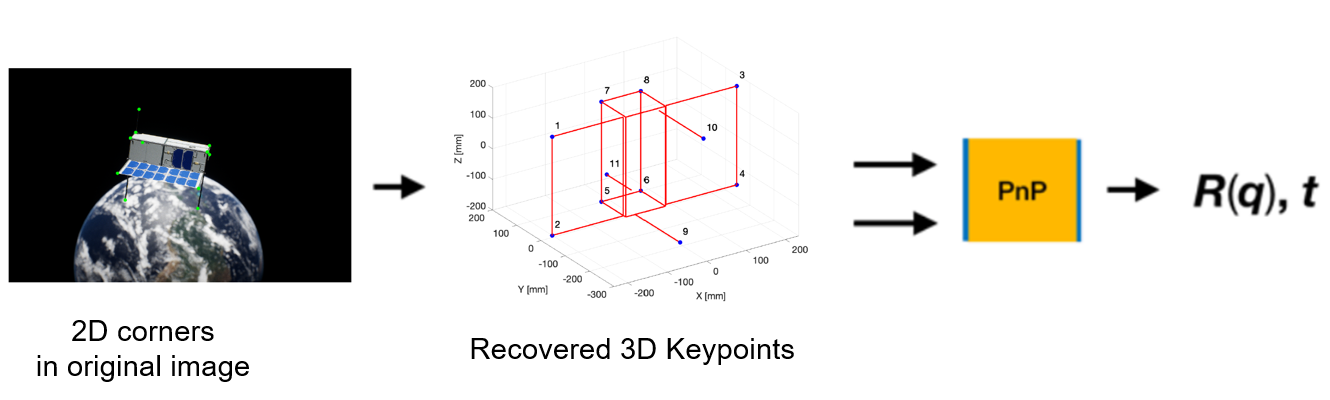

imshow(img); hold on; 
scatter(kpts_pr(1,:), kpts_pr(2,:), 16, 'rx', LineWidth=10);

title(["Spacecraft Image with 11 Keypoints"; "Projected from World to Image Frame"])
hold off

### Plot Camera and Satellite Location

Take the 2D keypoints and convert them into 3D space. Display a camera that shows the point and direction that the 2D "photo" was taken. 

[dcmPredictedSpacecraft,rPredictedSpacecraft] = estimateWorldCameraPose(kpts_pr',pointsTangoBodyRef,cameraParamMatlab);

pointsColorMap = [1 1 1; 1 0 0; 1 0 0; 1 0 0; 0 1 0; 0 1 0; 0 1 0; 0 1 0; 1 1 0; 1 1 0; 1 1 0];
h = pcshow(pointsTangoBodyRef,pointsColorMap,"VerticalAxis","Y","VerticalAxisDir","up","MarkerSize",100);
hold on
plotSpacecraftWireframe(pointsTangoBodyRef);
plotCamera("Size",0.15,"Orientation",dcmPredictedSpacecraft,"Location",rPredictedSpacecraft);
axis equal;
hold off
set(gca, 'View', [ -129.1886   15.8252])
title(["Position of camera in 3D space"; "to take previous 2D photo (distance in m)"])

Next, the generated attitude and range are converted from the spacecraft frame to the camera frame and displayed. The attitude is also converted from a dcm to a quaternian.

qPredictedCamera = dcm2quat(dcmPredictedSpacecraft')';
rPredictedCamera = dcmPredictedSpacecraft*(-rPredictedSpacecraft'); % how far camera is in x, y, and z. sqrt of these is actual distance
qGroundtruth = dataGroundTruth(sampleSelector).q_vbs2tango_true;
rGroundtruth = dataGroundTruth(sampleSelector).r_Vo2To_vbs_true; % ground truth of camera distance

The predicted quaternions and range are compared to the groundtruth version to calculate their error.

% References for the following metrics

    % https://www.mathworks.com/matlabcentral/answers/415936-angle-between-2-quaternions
    % https://www.mathworks.com/matlabcentral/answers/476474-how-to-find-the-angle-between-two-quaternions

qError = quatmultiply(quatconj(qPredictedCamera'),qGroundtruth');
degError = 2*atan2d(norm(qError(2:4)),qError(1));
if degError > 180
    degError = degError - 360;
end
degError;
rError = abs(norm(rPredictedCamera) - norm(rGroundtruth))

rError = 0.5609

After calculating metrics, we will show a comparison of the calculated spacecraft orientation vs the original ground truth.

coordPredicted = computeAxisCoordinates(cameraParamMatlab,qPredictedCamera',rPredictedCamera);
coordGroundtruth = computeAxisCoordinates(cameraParamMatlab,qGroundtruth',rGroundtruth);

The predicted points are plotted along with a plot of the groundtruth data. The error values are also shown on the plot.

figure(); montage({plotSpacecraftAxes(img,coordPredicted),plotSpacecraftAxes(img,coordGroundtruth)})
title("Spacecraft Image with Predicted vs Groundtruth Axis")
text(10,80,['Angle Error: ', num2str(degError),' deg'],"Color",[0 1 0], "BackgroundColor", "k")
text(10,170,['Range Error: ', num2str(rError),' m'],"Color",[0 1 0], "BackgroundColor", "k")